disp("Independent work 08 - interpolation 03.")

Independent work 08 - interpolation 03.


disp("Question 01.")

Question 01.



disp("first note : the matrices & equations are calculated in the upper half of this script ;")

first note : the matrices & equations are calculated in the upper half of this script ;


disp("second note : the matrices & equations are displayed in the lower half of this script ;")

second note : the matrices & equations are displayed in the lower half of this script ;



% Clear workspace and command window
clear;
clc;

% Cubic spline interpolation with matrix representation
disp("Process: Cubic Spline Interpolation (with matrix representation).");

Process: Cubic Spline Interpolation (with matrix representation).



% Define the given data points
x = [3, 4, 5, 6]  % x-coordinates

x =      3     4     5     6


y = [1.8353, 1.9633, 1.9453, 2.2797]  % y-coordinates

y =     1.8353    1.9633    1.9453    2.2797



% Number of intervals
n = length(x) - 1

n = 3


% Step 1: Setting up the system of equations as matrices
disp('Setting up the system of equations for the cubic spline ...');

Setting up the system of equations for the cubic spline ...



% Define the number of equations and variables
num_intervals = n  % Number of intervals

num_intervals = 3

num_coefficients = 4 * num_intervals % Total coefficients for all spline segments

num_coefficients = 12


% Initializing A and B matrices
disp("Initializing A and B matrices ...")

Initializing A and B matrices ...


A = zeros(num_coefficients, num_coefficients)

A =      0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0


B = zeros(num_coefficients, 1)

B =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



% Fill A and B based on the cubic spline conditions

% 1. Continuity of spline at data points
row = 1;
for i = 1:num_intervals
    % At x(i): S(i)(x(i)) = y(i)
    A(row, (i-1)*4+1:i*4) = [1, 0, 0, 0];
    B(row) = y(i);
    row = row + 1;
    
    % At x(i+1): S(i)(x(i+1)) = y(i+1)
    A(row, (i-1)*4+1:i*4) = [1, x(i+1)-x(i), (x(i+1)-x(i))^2, (x(i+1)-x(i))^3];
    B(row) = y(i+1);
    row = row + 1;
end

% 2. First derivative continuity
for i = 1:num_intervals-1
    A(row, (i-1)*4+2:i*4) = [1, 2*(x(i+1)-x(i)), 3*(x(i+1)-x(i))^2];
    A(row, i*4+2:i*4+4) = [-1, 0, 0];
    B(row) = 0;
    row = row + 1;
end

% 3. Second derivative continuity
for i = 1:num_intervals-1
    A(row, (i-1)*4+3:i*4) = [2, 6*(x(i+1)-x(i))];
    A(row, i*4+3:i*4+4) = [-2, 0];
    B(row) = 0;
    row = row + 1;
end

% 4. Boundary conditions (natural spline)
% Second derivative at the first point is zero
A(row, 3) = 2;
B(row) = 0;
row = row + 1;

% Second derivative at the last point is zero
A(row, end-1) = 2;
B(row) = 0;

% Resulting matrices for A & B variables
disp('Resulting matrix A (coefficients):');

Resulting matrix A (coefficients):


disp(A);

     1     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     1     1     1     1     0     0     0     0
     0     0     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     1     1     1     1
     0     1     2     3     0    -1     0     0     0     0     0     0
     0     0     0     0     0     1     2     3     0    -1     0     0
     0     0     2     6     0     0    -2     0     0     0     0     0
     0     0     0     0     0     0     2     6     0     0    -2     0
     0     0     2     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     2     0



disp('Resulting vector B (right-hand side):');

Resulting vector B (right-hand side):


disp(B);

    1.8353
    1.9633
    1.9633
    1.9453
    1.9453
    2.2797
         0
         0
         0
         0
         0
         0




% Step 2: Solve the system
disp('Solving the linear system ...');

Solving the linear system ...


X = A \ B;

% Step 3: Display solution matrix
disp('Solution X (spline coefficients):');

Solution X (spline coefficients):


disp(X);

    1.8353
    0.1645
         0
   -0.0365
    1.9633
    0.0550
   -0.1095
    0.0365
    1.9453
   -0.0545
         0
    0.3889




% Step 4: Display the spline equations
disp('Spline equations for each interval:');

Spline equations for each interval:


for i = 1:num_intervals
    a = X((i-1)*4+1);
    b = X((i-1)*4+2);
    c = X((i-1)*4+3);
    d = X((i-1)*4+4);
    fprintf('S%d(x) = %.4f + %.4f*(x - %.1f) + %.4f*(x - %.1f)^2 + %.4f*(x - %.1f)^3\n', ...
        i, a, b, x(i), c, x(i), d, x(i));
end

S1(x) = 1.8353 + 0.1645*(x - 3.0) + 0.0000*(x - 3.0)^2 + -0.0365*(x - 3.0)^3
S2(x) = 1.9633 + 0.0550*(x - 4.0) + -0.1095*(x - 4.0)^2 + 0.0365*(x - 4.0)^3
S3(x) = 1.9453 + -0.0545*(x - 5.0) + 0.0000*(x - 5.0)^2 + 0.3889*(x - 5.0)^3



% Step 5: Plot the cubic spline interpolation
disp('Plotting the cubic spline ...');

Plotting the cubic spline ...


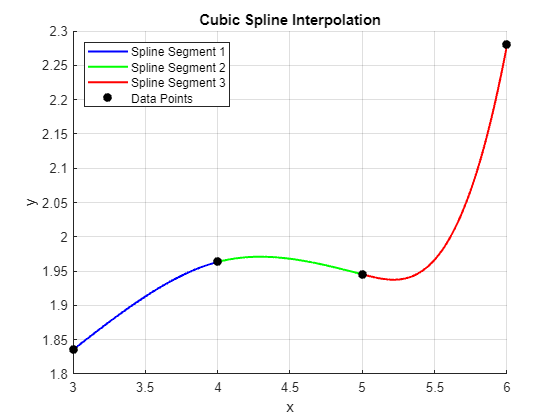


% Define the spline functions for plotting
hold on;
colors = ['b', 'g', 'r', 'm']; % Different colors for each segment
for i = 1:num_intervals
    a = X((i-1)*4+1);
    b = X((i-1)*4+2);
    c = X((i-1)*4+3);
    d = X((i-1)*4+4);
    xx = linspace(x(i), x(i+1), 100);
    yy = a + b*(xx - x(i)) + c*(xx - x(i)).^2 + d*(xx - x(i)).^3;
    plot(xx, yy, 'Color', colors(mod(i-1, length(colors))+1), 'LineWidth', 1.5);
end

% Plot the original data points
plot(x, y, 'ko', 'MarkerFaceColor', 'k', 'DisplayName', 'Data Points');

% Customize plot
title('Cubic Spline Interpolation');
xlabel('x');
ylabel('y');
legend('Spline Segment 1', 'Spline Segment 2', 'Spline Segment 3', 'Data Points', 'Location', 'NorthWest');
grid on;
hold off;


disp('The end.');

The end.
